**Activity. **Adjust the sliders to view different time-domain responses for the classical second-order system:

    
$$G(s) = \frac{ K }{s^2 + 2 \zeta \omega_n s  + \omega_n^2$$


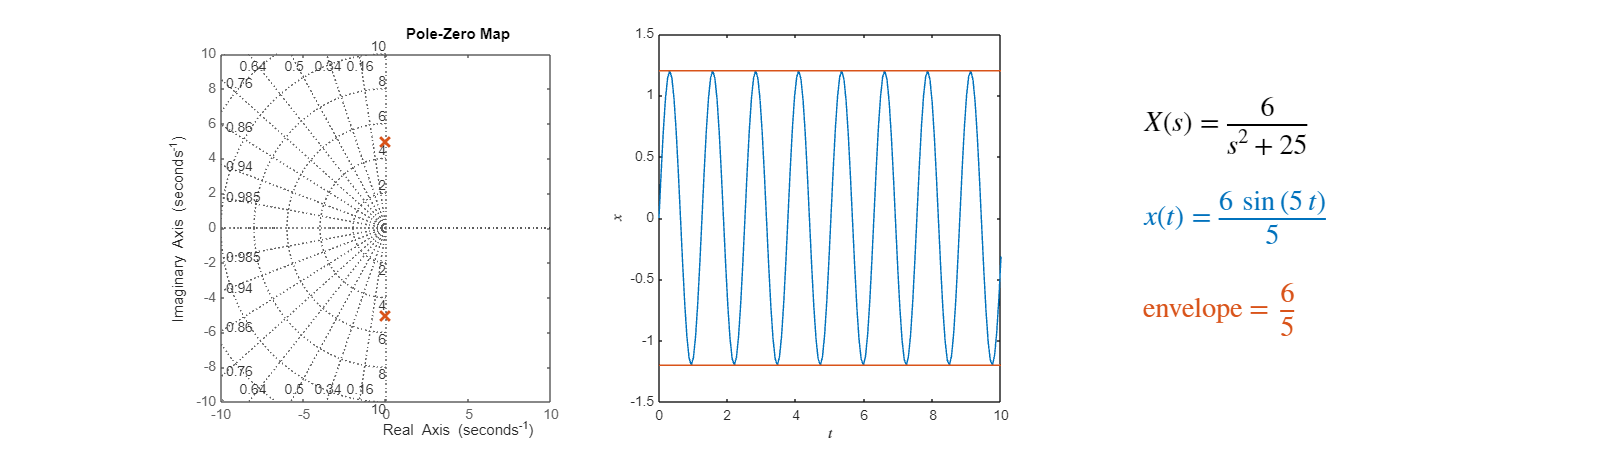

K = 6;
zeta = 0;
omega_n = 5;

plotNaturalResponse(zeta,omega_n,K) % Helper function that plots the response for the second order system

**  Reflect.** 

- Does the carrier frequency of the solution change with the damping coefficient $\zeta$?

- Does the exponential envelope change with $\omega_n$?

- How does the gain $K$ affect the response?

function plotNaturalResponse(zeta,omega_n,K)
% Plots the natural frequency response
    b = 2*zeta*omega_n;
    c = omega_n^2;
    H = tf([0 0 K],[1 b c]);
    
    syms s X x t
    X = K/(s^2 + b*s + c);
    x = ilaplace(X);
    envelope = K*exp(-omega_n*t*zeta)/(omega_n*sqrt(1-zeta^2));
    
    % Plot the poles and impulse response
    figure("Position",[0 0 1600 450])

    subplot(1,3,1)
    pzmap(H,"b")
    grid on
    axis equal
    lineObjs = findobj(gca,"Type","Line");   
    axis([-10 10 -10 10])
    set(lineObjs(3),"MarkerSize",10,"LineWidth",2,"Color",[0.8500 0.3250 0.0980]);           
    
    subplot(1,3,2)
    [y,t] = impulse(H,10);
    ev = K*exp(-omega_n*zeta*t)/(omega_n*sqrt(1-zeta^2));
    plot(t,y)
    hold on
    plot(t,ev,"Color",[0.8500 0.3250 0.0980])
    plot(t,-ev,"Color",[0.8500 0.3250 0.0980])
    hold off
    xlabel('$t$',"Interpreter","latex")
    ylabel('$x$',"Interpreter","latex")
    
    subplot(1,3,3)
    axis([-0.1 1 0 1])
    text(0,0.75,"$X(s) = " +latex(X)+"$","Interpreter","latex","FontSize",20)
    text(0,0.5,"$x(t) = " +latex(x)+"$","Interpreter","latex","FontSize",20,"Color",[0 0.4470 0.7410])
    if(zeta < 1)
        text(0,0.25,"envelope = $" +latex(envelope)+"$","Interpreter","latex","FontSize",20,"Color",[0.8500 0.3250 0.0980])
    end
    axis off 
   

end